# "How to load data": (Example of scenario 1)


%  The HDF-5 file stores **one row per Wi-Fi packet**.  The main integer columns let you
%  slice the big table quickly:
%
%      ▸ room_id     : 0 → Room A   ·  1 → Room B
%      ▸ setting_id  : 0 → ‘_1’     ·  1 → ‘_2’
%      ▸ pkt_idx     : running index *within* each (room,setting) trace
%      ▸ seg_idx     : 0 … 149  (150 two-second windows per trace)
%
%  All other datasets share the first dimension:
%      td_us – micro-second time-stamp (int64)
%      rssi  – [N,2] float32   ·  mcs – uint8
%      gain  – [N,2] complex64 ·  csi – [N,subc,ant] complex64
%
%  MATLAB’s HDF-5 interface reads native complex automatically.  A quick
%  peek at the structure:
h5disp("packets_scenario_1.h5","/")

HDF5 packets_scenario_1.h5 
Group '/' 
    Dataset 'csi' 
        Size:  4x250x26821
        MaxSize:  4x250x26821
        Datatype:   H5T_COMPOUND
            Member 'r':  H5T_IEEE_F32LE (single)
            Member 'i':  H5T_IEEE_F32LE (single)
        ChunkSize:  1x16x839
        Filters:  shuffle, deflate(4)
        FillValue:  H5T_COMPOUND
    Dataset 'gain' 
        Size:  2x26821
        MaxSize:  2x26821
        Datatype:   H5T_COMPOUND
            Member 'r':  H5T_IEEE_F32LE (single)
            Member 'i':  H5T_IEEE_F32LE (single)
        ChunkSize:  1x1677
        Filters:  shuffle, deflate(4)
        FillValue:  H5T_COMPOUND
    Dataset 'mcs' 
        Size:  26821
        MaxSize:  26821
        Datatype:   H5T_STD_U8LE (uint8)
        ChunkSize:  6706
        Filters:  shuffle, deflate(4)
        FillValue:  0
    Dataset 'pkt_idx' 
        Size:  26821
        MaxSize:  26821
        Datatype:   H5T_STD_I32LE (int32)
        ChunkSize:  1677
        Filters:  shuffle, defl

## 1.  Load the index columns (cheap – they are uint / int64)

room_id   = h5read("packets_scenario_1.h5","/room_id");      % [N  ] uint8
setting_id= h5read("packets_scenario_1.h5","/setting_id");   % [N  ] uint8
pkt_idx   = h5read("packets_scenario_1.h5","/pkt_idx");      % [N  ] int32
seg_idx   = h5read("packets_scenario_1.h5","/seg_idx");      % [N  ] int32


## 2.  Choose a **room / setting / segment** of interest

% Different segments have a different number of packets
ROOM    = 0;      % 0 → Room A , 1 → Room B
SETTING = 1;      % 0 → “_1”   , 1 → “_2”
SEGMENT =  23;    % 0 … 149

sel = (room_id   == ROOM   ) & ...
      (setting_id== SETTING) & ...
      (seg_idx   == SEGMENT);

% number of packets inside this 2-s window
n_pkts = nnz(sel);
fprintf("Segment %d of Room %d / Setting %d has %d packets\n", ...
        SEGMENT, ROOM, SETTING, n_pkts)

Segment 23 of Room 0 / Setting 1 has 46 packets


## 3.  Read *only those packets* for each variable

read_sel = @(path) h5read("packets_scenario_1.h5", path, ...
                          fliplr(find(sel,1,'first')),        ...
                          [nnz(sel); ones( ndims(h5info("packets_scenario_1.h5",path).Dataspace.Size)-1 ,1)]);

td_us = h5read("packets_scenario_1.h5","/td_us");
td_us = td_us(sel);                       % micro-second time-stamps

rssi  = h5read("packets_scenario_1.h5","/rssi");   rssi  = rssi(:,sel).';   % [n_pkts,2]
mcs   = h5read("packets_scenario_1.h5","/mcs");    mcs   = mcs(sel);        % [n_pkts,1]

gain  = h5read("packets_scenario_1.h5","/gain");                           % struct → complex
gain  = complex(gain.r, gain.i);        gain  = gain(:,sel).';

csi   = h5read("packets_scenario_1.h5","/csi");                            % [250,4, N] or [248,4, N]
csi = complex(csi.r(:,:,sel), csi.i(:,:,sel));
csi

csi = 4×250×46 single array
csi(:,:,1) =

   1.0e-04 *

  -0.0070 + 0.0115i   0.0059 + 0.0181i   0.0170 + 0.0096i   0.0204 - 0.0048i   0.0137 - 0.0192i  -0.0037 - 0.0252i  -0.0218 - 0.0159i  -0.0285 + 0.0048i  -0.0196 + 0.0252i   0.0037 + 0.0344i   0.0285 + 0.0222i   0.0363 - 0.0022i   0.0241 - 0.0263i  -0.0022 - 0.0366i  -0.0296 - 0.0237i  -0.0400 + 0.0063i  -0.0252 + 0.0344i   0.0052 + 0.0448i   0.0344 + 0.0303i   0.0485 - 0.0022i   0.0337 - 0.0370i  -0.0004 - 0.0518i  -0.0359 - 0.0363i  -0.0544 - 0.0007i  -0.0400 + 0.0385i  -0.0030 + 0.0570i   0.0377 + 0.0429i   0.0585 + 0.0037i   0.0448 - 0.0426i   0.0000 - 0.0640i  -0.0470 - 0.0481i  -0.0696 - 0.0011i  -0.0518 + 0.0488i  -0.0074 + 0.0710i   0.0429 + 0.0607i   0.0751 + 0.0159i   0.0670 - 0.0400i   0.0211 - 0.0751i  -0.0363 - 0.0688i  -0.0751 - 0.0248i  -0.0770 + 0.0337i  -0.0374 + 0.0829i   0.0303 + 0.0899i   0.0851 + 0.0433i   0.0910 - 0.0303i   0.0481 - 0.0866i  -0.0204 - 0.1014i  -0.0844 - 0.0655i  -0.1088 + 0.0085i  -0.0766 + 0

## 4.  Quick visual sanity check

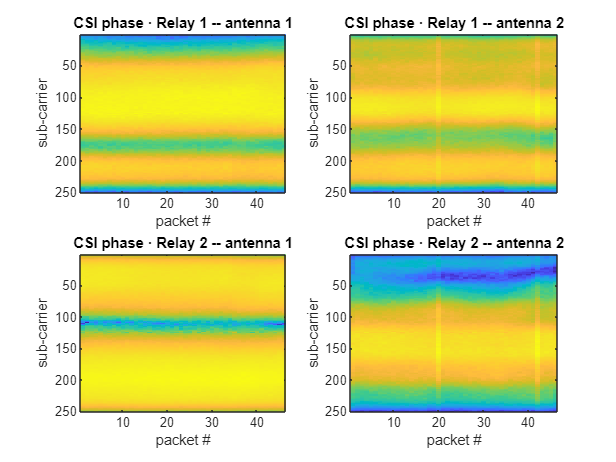

figure
subplot(2,2,1)
csi_db_1 = 20*log10(abs(squeeze(csi(1, :, :))));
imagesc(csi_db_1)        % unwrap first antenna
xlabel('packet #'), ylabel('sub-carrier')
title('CSI phase · Relay 1 -- antenna 1')
subplot(2,2,2)
csi_db_2 = 20*log10(abs(squeeze(csi(2, :, :))));
imagesc(csi_db_2)        % unwrap the second antenna
xlabel('packet #'), ylabel('sub-carrier')
title('CSI phase · Relay 1 -- antenna 2')

subplot(2,2,3)
csi_db_3 = 20*log10(abs(squeeze(csi(3, :, :))));
imagesc(csi_db_3)        % unwrap first antenna
xlabel('packet #'), ylabel('sub-carrier')
title('CSI phase · Relay 2 -- antenna 1')
subplot(2,2,4)
csi_db_4 = 20*log10(abs(squeeze(csi(4, :, :))));
imagesc(csi_db_4)        % unwrap the second antenna
xlabel('packet #'), ylabel('sub-carrier')
title('CSI phase · Relay 2 -- antenna 2')